# Stoichiometrically or kinetically constrained scan

Initialize the project

project_name = 'ecYeast';
project_path = findECOMAProot;
InitializeECOMAPproject(project_name, project_path);
ParameterManagerLocation = fullfile(findECOMAProot, project_name, [project_name 'ParameterManagement.m']); 
ParameterManager.getParams(ParameterManagerLocation);

Initiation model

GEM = loadModel('Yeast9.yml', 'Tradition');
T = readtable(fullfile(findECOMAProot, 'projects', project_name, 'calibration','data', 'UnconstrainedMaxGrowth.tsv'), 'FileType', 'text', 'ReadRowNames', true);
ex_rxn_list = unique(T.Substrate);
ex_rxn_list = ex_rxn_list(~strcmp(ex_rxn_list, 'NaN'));
load(fullfile(findECOMAProot, 'projects', project_name,'models','ecYeast9-integrated.mat'))
[ecYeast9_integrated, sluiceConfig] = applySluiceStructure(ecYeast9_integrated, ex_rxn_list);

[applySluiceStructure] Applying sluice structure to 8 reactions...
  Applied: r_1634 -> r_1634_basal + r_1634_extended
  Applied: r_1709 -> r_1709_basal + r_1709_extended
  Applied: r_1710 -> r_1710_basal + r_1710_extended
  Applied: r_1714 -> r_1714_basal + r_1714_extended
  Applied: r_1715 -> r_1715_basal + r_1715_extended
  Applied: r_1761 -> r_1761_basal + r_1761_extended
  Applied: r_1931 -> r_1931_basal + r_1931_extended
  Applied: r_2058 -> r_2058_basal + r_2058_extended
[applySluiceStructure] Done. Model now has sluice structure.


kcatRepo = KcatRepo.loadMat('calibration/ecYeast9_kcatRepo.mat');
groupNames = kcatRepo.listGroups();
ecGEM = kcatRepo.applyToModel(ecYeast9_integrated, 'mSA_ABC_SMF_GAUKS');

[KcatRepo] Applying group: mSA_ABC_SMF_GAUKS
[setSluiceParams] Set r_1634: Umin=1000.0000, Xi=1.0000
[setSluiceParams] Set r_1709: Umin=3.8264, Xi=0.9003
[setSluiceParams] Set r_1710: Umin=3.2780, Xi=60.5469
[setSluiceParams] Set r_1714: Umin=1000.0000, Xi=1.0000
[setSluiceParams] Set r_1715: Umin=1000.0000, Xi=1.0000
[setSluiceParams] Set r_1761: Umin=3.8181, Xi=7.8125
[setSluiceParams] Set r_1931: Umin=1000.0000, Xi=1.0000
[setSluiceParams] Set r_2058: Umin=2.2048, Xi=0.1163
[KcatRepo] Done.


ecGEM = UpdateSmatrix(ecGEM);

Scan native products and export Fig. 1E coordinates

%% Scan products, classify the active limitation, and plot Fig. 1E coordinates
% Domenzain et al. classification criterion:
% compare GEM and ecGEM maximum production under the same low-glucose
% condition (glucose uptake <= 1 mmol/gDW/h). A significant contraction of
% the ecGEM maximum indicates an active kinetic/enzyme-capacity constraint;
% overlapping maxima indicate a stoichiometric/substrate constraint. The
% minimum-protein solution is retained as an enzyme-occupancy diagnostic.
designDir = fullfile(findECOMAProot, 'projects', project_name, 'design', 'metabolite_scan');
if ~isfolder(designDir)
    mkdir(designDir);
end
scanFile = fullfile(designDir, 'metabolite_scan.xlsx');
assert(isfile(scanFile), ...
    'Input workbook is missing: %s', scanFile);
scanSheet = 'TableS1_mapping';
products = readtable(scanFile, 'Sheet', scanSheet, 'TextType', 'string', ...
    'VariableNamingRule', 'preserve');

requiredColumns = ["Name", "Chemical class", "limitation", "Exchange reaction ID"];
assert(all(ismember(requiredColumns, string(products.Properties.VariableNames))), ...
    'metabolite_scan.xlsx must contain Name, Chemical class, limitation, and Exchange reaction ID columns.');
productIDs = products.("Exchange reaction ID");
productNames = products.("Name");
assert(numel(unique(productIDs)) == height(products), ...
    'Duplicate exchange reaction IDs were found in metabolite_scan.xlsx.');
assert(all(ismember(productIDs, string(GEM.rxns))), ...
    'At least one product exchange reaction is absent from GEM.');
assert(all(ismember(productIDs, string(ecGEM.rxns))), ...
    'At least one product exchange reaction is absent from ecGEM.');

% Reproduce the paper's mineral-minimal-medium setup. In this model,
% exchange uptake is negative, so all uptake is first blocked with LB = 0.
[~, exchangeIdx] = getExchangeRxns(ecGEM);
scanBase = ecGEM;
scanBase.lb(exchangeIdx) = 0;
[~, gemExchangeIdx] = getExchangeRxns(GEM);
gemBase = GEM;
gemBase.lb(gemExchangeIdx) = 0;

poolIdx = find(strcmp(scanBase.rxns, 'prot_pool_exchange'), 1);
assert(~isempty(poolIdx), 'prot_pool_exchange is absent from ecGEM.');
scanBase.lb(poolIdx) = ecGEM.lb(poolIdx);
scanBase.ub(poolIdx) = 0;
proteinPoolCapacity = abs(scanBase.lb(poolIdx));
assert(isfinite(proteinPoolCapacity) && proteinPoolCapacity > 0, ...
    'prot_pool_exchange must have a finite negative lower bound.');

mineralUptakeIDs = {'r_1654','r_2100','r_1861','r_1992','r_2005', ...
    'r_2060','r_1832','r_4593','r_4595','r_4596','r_4597','r_2049', ...
    'r_4594','r_4600','r_2020'};
assert(all(ismember(mineralUptakeIDs, scanBase.rxns)), ...
    'One or more mineral-medium exchange reactions are absent from ecGEM.');
for j = 1:numel(mineralUptakeIDs)
    scanBase.lb(strcmp(scanBase.rxns, mineralUptakeIDs{j})) = -1000;
    gemBase.lb(strcmp(gemBase.rxns, mineralUptakeIDs{j})) = -1000;
end

glucoseIdx = find(strcmp(scanBase.rxns, 'r_1714'), 1);
biomassIdx = find(strcmp(scanBase.rxns, 'r_2111'), 1);
assert(~isempty(glucoseIdx) && ~isempty(biomassIdx), ...
    'Glucose exchange r_1714 or biomass r_2111 is absent from ecGEM.');
scanBase.lb(glucoseIdx) = -1;
scanBase.ub(glucoseIdx) = 0;
scanBase.lb(biomassIdx) = 0;
scanBase.ub(biomassIdx) = 1000;
gemGlucoseIdx = find(strcmp(gemBase.rxns, 'r_1714'), 1);
gemBiomassIdx = find(strcmp(gemBase.rxns, 'r_2111'), 1);
gemBase.lb(gemGlucoseIdx) = -1;
gemBase.ub(gemGlucoseIdx) = 0;
gemBase.lb(gemBiomassIdx) = 0;
gemBase.ub(gemBiomassIdx) = 1000;

blockedOutputIDs = {'r_1663','r_4062','r_4064'};
for j = 1:numel(blockedOutputIDs)
    idx = find(strcmp(scanBase.rxns, blockedOutputIDs{j}), 1);
    if ~isempty(idx)
        scanBase.ub(idx) = 0;
    end
    gemIdx = find(strcmp(gemBase.rxns, blockedOutputIDs{j}), 1);
    if ~isempty(gemIdx)
        gemBase.ub(gemIdx) = 0;
    end
end

% In this integrated ECOMAP model, MW/kcat is embedded in S. Therefore,
% |usage_prot_* flux| is enzyme mass in mg/gDW.
usageIdx = find(startsWith(scanBase.rxns, 'usage_prot_'));
assert(~isempty(usageIdx), 'No usage_prot_* reactions were found in ecGEM.');
assert(all(scanBase.ub(usageIdx) <= 0), ...
    'Unexpected enzyme-usage sign convention: usage reactions must be non-positive.');

nProducts = height(products);
substrateCost = nan(nProducts, 1);
proteinCost = nan(nProducts, 1);
enzymeMassFraction = nan(nProducts, 1);
effectiveGlucoseUptake = nan(nProducts, 1);
gemMaxProductFlux = nan(nProducts, 1);
ecToGemMaxRatio = nan(nProducts, 1);
modelLimitation = repmat("not_calculated", nProducts, 1);
scanStatus = repmat("infeasible_or_zero_production", nProducts, 1);
glucoseMW_g_per_mmol = 0.180156;
optimalityTolerance = 1e-8;
minimumProductFlux = 1e-9;
constraintClassificationTolerance = 1e-5;

for i = 1:nProducts
    productID = char(productIDs(i));
    productIdx = find(strcmp(scanBase.rxns, productID), 1);

    gemProductIdx = find(strcmp(GEM.rxns, productID), 1);
    productMetIdx = find(GEM.S(:, gemProductIdx) ~= 0);
    assert(numel(productMetIdx) == 1, ...
        'Candidate %s is not a single-metabolite exchange reaction in GEM.', productID);
    productMW_g_per_mol = getMolecularMass(GEM.metFormulas{productMetIdx}, 0);
    assert(isfinite(productMW_g_per_mol) && productMW_g_per_mol > 0, ...
        'No valid molecular mass could be calculated for %s.', productID);

    gemProductModel = gemBase;
    gemProductModel.lb(gemProductIdx) = 0;
    gemProductModel.ub(gemProductIdx) = 1000;
    gemProductModel.c(:) = 0;
    gemProductModel.c(gemProductIdx) = 1;
    gemSolution = solveLP(gemProductModel);
    if ~isempty(gemSolution.x) && gemSolution.stat >= 0
        gemMaxProductFlux(i) = gemSolution.x(gemProductIdx);
    end

    % Primary FBA: maximize product secretion at glucose uptake <= 1.
    productModel = scanBase;
    productModel.lb(productIdx) = 0;
    productModel.ub(productIdx) = 1000;
    productModel.c(:) = 0;
    productModel.c(productIdx) = 1;
    productSolution = solveLP(productModel);
    if isempty(productSolution.x) || productSolution.stat < 0 || ...
            productSolution.x(productIdx) <= minimumProductFlux
        continue
    end
    optimalProductFlux = productSolution.x(productIdx);

    % Retain maximal production and minimize the ACTUAL glucose uptake.
    % Uptake flux is negative in this model, so maximizing v_glucose makes it
    % as close to zero as possible and therefore minimizes |v_glucose|. The
    % bound -1 is only a capacity; it is not substituted into the cost formula.
    substrateModel = productModel;
    substrateModel.lb(productIdx) = optimalProductFlux * (1 - optimalityTolerance);
    substrateModel.c(:) = 0;
    substrateModel.c(glucoseIdx) = 1;
    substrateSolution = solveLP(substrateModel, 1);

    % Retain maximal production and minimize ACTUAL enzyme usage. Enzyme-usage
    % fluxes are negative, so maximizing their sum minimizes sum(abs(usage)).
    % The protein-pool bound remains a capacity and is not used as consumption.
    proteinModel = productModel;
    proteinModel.lb(productIdx) = optimalProductFlux * (1 - optimalityTolerance);
    proteinModel.c(:) = 0;
    proteinModel.c(usageIdx) = 1;
    proteinSolution = solveLP(proteinModel, 1);

    if isempty(substrateSolution.x) || substrateSolution.stat < 0 || ...
            isempty(proteinSolution.x) || proteinSolution.stat < 0
        scanStatus(i) = "secondary_optimization_failed";
        continue
    end

    substrateProductMass = substrateSolution.x(productIdx) * productMW_g_per_mol / 1000;
    proteinProductMass = proteinSolution.x(productIdx) * productMW_g_per_mol / 1000;
    effectiveGlucoseUptake(i) = abs(substrateSolution.x(glucoseIdx));
    actualEnzymeMass_g_per_gDW = sum(abs(proteinSolution.x(usageIdx))) / 1000;
    substrateCost(i) = effectiveGlucoseUptake(i) * ...
        glucoseMW_g_per_mmol / substrateProductMass;
    proteinCost(i) = actualEnzymeMass_g_per_gDW / proteinProductMass;

    enzymeMassFraction(i) = sum(abs(proteinSolution.x(usageIdx))) / proteinPoolCapacity;
    ecToGemMaxRatio(i) = optimalProductFlux / gemMaxProductFlux(i);
    if ecToGemMaxRatio(i) < 1 - constraintClassificationTolerance
        modelLimitation(i) = "kinetic";
    else
        modelLimitation(i) = "stoichiometric";
    end
    scanStatus(i) = "ok";
end

valid = scanStatus == "ok" & isfinite(substrateCost) & isfinite(proteinCost);
if any(~valid)
    warning('%d products have no finite ecGEM coordinate pair and will be marked not_calculated.', nnz(~valid));
    disp(table(productNames(~valid), productIDs(~valid), scanStatus(~valid), ...
        'VariableNames', {'Name','reaction_id','status'}));
end

% Write the local classification and both Fig. 1E coordinates while
% preserving the paper-derived columns and the rest of the workbook.
variableNames = string(products.Properties.VariableNames);
nextOutputColumnIndex = width(products) + 1;

modelLimitationColumnIndex = find(strcmpi(variableNames, 'model_limitation'), 1);
if isempty(modelLimitationColumnIndex)
    modelLimitationColumnIndex = nextOutputColumnIndex;
    nextOutputColumnIndex = nextOutputColumnIndex + 1;
else
    nextOutputColumnIndex = max(nextOutputColumnIndex, modelLimitationColumnIndex + 1);
end

substrateCostColumnName = 'substrate_cost_g_glucose_per_g_product';
substrateCostColumnIndex = find(strcmpi(variableNames, substrateCostColumnName), 1);
if isempty(substrateCostColumnIndex)
    substrateCostColumnIndex = nextOutputColumnIndex;
    nextOutputColumnIndex = nextOutputColumnIndex + 1;
else
    nextOutputColumnIndex = max(nextOutputColumnIndex, substrateCostColumnIndex + 1);
end

proteinCostColumnName = 'protein_cost_g_protein_per_g_product';
proteinCostColumnIndex = find(strcmpi(variableNames, proteinCostColumnName), 1);
if isempty(proteinCostColumnIndex)
    proteinCostColumnIndex = nextOutputColumnIndex;
else
    nextOutputColumnIndex = max(nextOutputColumnIndex, proteinCostColumnIndex + 1);
end

assert(max([modelLimitationColumnIndex, substrateCostColumnIndex, ...
    proteinCostColumnIndex]) <= 26, 'An output column exceeds column Z.');
modelLimitationColumnLetter = char(double('A') + modelLimitationColumnIndex - 1);
substrateCostColumnLetter = char(double('A') + substrateCostColumnIndex - 1);
proteinCostColumnLetter = char(double('A') + proteinCostColumnIndex - 1);

substrateCostCells = num2cell(substrateCost);
proteinCostCells = num2cell(proteinCost);
substrateCostCells(~isfinite(substrateCost)) = {''};
proteinCostCells(~isfinite(proteinCost)) = {''};
writecell([{'model_limitation'}; cellstr(modelLimitation)], scanFile, ...
    'Sheet', scanSheet, 'Range', sprintf('%s1', modelLimitationColumnLetter));
writecell([{substrateCostColumnName}; substrateCostCells], scanFile, ...
    'Sheet', scanSheet, 'Range', sprintf('%s1', substrateCostColumnLetter));
writecell([{proteinCostColumnName}; proteinCostCells], scanFile, ...
    'Sheet', scanSheet, 'Range', sprintf('%s1', proteinCostColumnLetter));

scanResults = table(productIDs, productNames, substrateCost, proteinCost, ...
    enzymeMassFraction, effectiveGlucoseUptake, gemMaxProductFlux, ecToGemMaxRatio, ...
    modelLimitation, scanStatus, ...
    'VariableNames', {'reaction_id','product_name', ...
    'substrate_cost_g_glucose_per_g_product', ...
    'protein_cost_g_protein_per_g_product', ...
    'protein_pool_occupancy_fraction', ...
    'effective_glucose_uptake_mmol_per_gDW_h', ...
    'gem_max_product_flux','ec_to_gem_max_ratio', ...
    'model_limitation','status'});

paperLimitation = lower(strtrim(products.("limitation")));
paperCategory = repmat("not_available", nProducts, 1);
substrateLabels = ["substrate", "stoichiometric", "stoichiometrically constrained"];
proteinLabels = ["protein", "kinetic", "kinetically constrained"];
paperCategory(ismember(paperLimitation, substrateLabels)) = "stoichiometric";
paperCategory(ismember(paperLimitation, proteinLabels)) = "kinetic";
recognizedPaperCategory = ismember(paperCategory, ["kinetic", "stoichiometric"]);
comparable = valid & recognizedPaperCategory;
agreement = comparable & paperCategory == modelLimitation;
fprintf('Classified %d/%d products: %d stoichiometric and %d kinetic; %d not calculated.\n', ...
    nnz(valid), nProducts, nnz(modelLimitation == "stoichiometric"), ...
    nnz(modelLimitation == "kinetic"), nnz(~valid));

Classified 40/40 products: 33 stoichiometric and 7 kinetic; 0 not calculated.


if nnz(comparable) == 0
    warning(['No valid Table S1 limitation labels were available for comparison. ' ...
        'Expected substrate/protein labels in the limitation column.']);
else
    fprintf('Agreement with the paper Table S1 limitation: %d/%d (%.1f%%).\n', ...
        nnz(agreement), nnz(comparable), 100 * nnz(agreement) / nnz(comparable));
end

Agreement with the paper Table S1 limitation: 37/40 (92.5%).


if any(comparable & ~agreement)
    disp(table(productNames(comparable & ~agreement), ...
        paperCategory(comparable & ~agreement), modelLimitation(comparable & ~agreement), ...
        ecToGemMaxRatio(comparable & ~agreement), enzymeMassFraction(comparable & ~agreement), ...
        'VariableNames', {'Name','paper_category','model_limitation', ...
        'ec_to_gem_max_ratio','enzyme_mass_fraction'}));
end

         Name          paper_category     model_limitation    ec_to_gem_max_ratio    enzyme_mass_fraction
    ______________    ________________    ________________    ___________________    ____________________

    "L-cysteine"      "stoichiometric"       "kinetic"              0.86408                   1          
    "L-proline"       "stoichiometric"       "kinetic"              0.99718                   1          
    "L-tryptophan"    "stoichiometric"       "kinetic"              0.69147                   1          



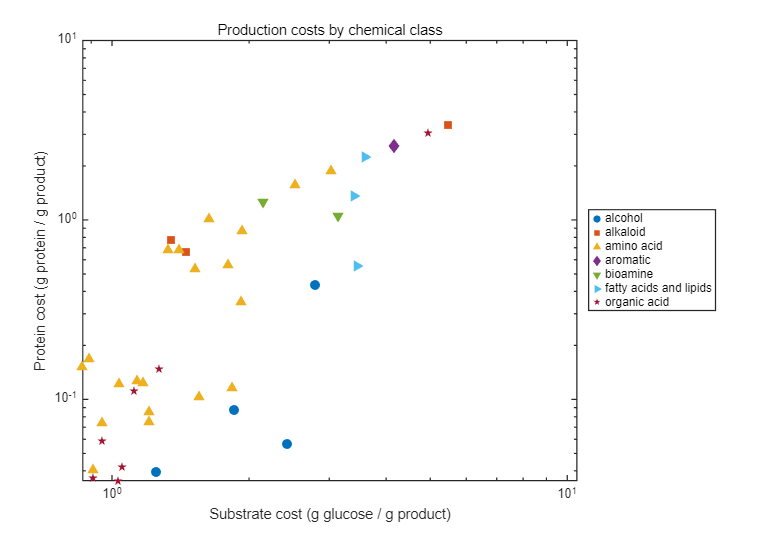


% Fig. 1E-style cost plot. Marker shape and color encode Chemical class.
chemicalClass = products.("Chemical class");
plotClasses = unique(chemicalClass(valid), 'stable');
markerList = {'o','s','^','d','v','>','p','h','<','x'};
assert(numel(plotClasses) <= numel(markerList), ...
    'More chemical classes were found than available plot markers.');
classColors = lines(numel(plotClasses));

figure('Color', 'w', 'Position', [100 100 860 600]);
hold on;
for classIndex = 1:numel(plotClasses)
    classMembers = valid & chemicalClass == plotClasses(classIndex);
    scatter(substrateCost(classMembers), proteinCost(classMembers), ...
        68, classColors(classIndex, :), markerList{classIndex}, 'filled', ...
        'DisplayName', char(plotClasses(classIndex)));
end
set(gca, 'XScale', 'log', 'YScale', 'log', 'FontSize', 11, 'LineWidth', 1);
% Keep both 10^0 and 10^1 visible instead of relying on automatic log ticks.
currentXLimits = xlim;
xlim([currentXLimits(1), max(10.5, currentXLimits(2))]);
xticks([1 10]);
xticklabels({'10^0','10^1'});
xlabel('Substrate cost (g glucose / g product)');
ylabel('Protein cost (g protein / g product)');
title('Production costs by chemical class');
legend('Location', 'eastoutside', 'Interpreter', 'none');
grid off;
box on;
hold off;
fig1EAxes = gca;
if isprop(fig1EAxes, 'Toolbar')
    fig1EAxes.Toolbar.Visible = 'off';
end
svgFile = fullfile(designDir, 'metabolite_scan_Fig1E.svg');
set(gcf, 'Renderer', 'painters');

print(gcf, svgFile, '-dsvg');
%% Generate one production envelope per product using the authors' code
% This section follows getYieldPlot.m from CellFactory-ecYeastGEM rather
% than the inconsistent mathematical description in the SI Appendix.
%
% Author-code behavior reproduced here:
%   * Low glucose: uptake is fixed approximately at 1 mmol/gDW/h.
%   * High glucose: uptake is bounded between 0 and 10 mmol/gDW/h.
%   * Maximum biomass (MiuMax) is solved separately for every model and
%     glucose condition.
%   * iterations = 10 but i = 1:iterations+1, giving 11 alpha values
%     0, 0.1, ..., 1.
%   * Biomass is imposed as a lower bound of 0.9999 * Drate, not equality.
%   * Both plotted yields are divided by the optimized glucose uptake GURsim.
glucoseUptakeCaps = [1 10];
nBiomassIntervals = 10;
alphaValues = (0:nBiomassIntervals) / nBiomassIntervals;
nBiomassPoints = numel(alphaValues);

modelNames = ["GEM" "ecGEM"];
conditionModelNumbers = [1 1 2 2];
conditionRegimeNumbers = [1 2 1 2];
conditionLabels = {'GEM low glucose','GEM high glucose', ...
    'ecGEM low glucose','ecGEM high glucose'};
% Exact MATLAB default ColorOrder used by the authors. Their plot order is
% ecGEM low (blue), ecGEM high (orange), GEM low (yellow), GEM high
% (purple); ecGEM curves are solid and GEM curves are dash-dot.
conditionColors = [0.9290 0.6940 0.1250; 0.4940 0.1840 0.5560; ...
    0.0000 0.4470 0.7410; 0.8500 0.3250 0.0980];
conditionLineStyles = {'-.','-.','-','-'};
% Widths decrease in the authors' series order. Thick curves are drawn
% first and the thinnest curve last, so coincident curves remain visible.
conditionLineWidths = [3.4 2.8 4.6 4.0];
conditionPlotOrder = [3 4 1 2];
% The published curves have no markers; overlap is handled by line width
% and z-order only, without shifting any numerical coordinates.
overlapMarkerConditions = [];
overlapMarkerSymbols = {'none','none','none','none'};

% getYieldPlot computes MiuMax after applying the glucose bounds for the
% current condition. Do the same once for each of our four conditions.
conditionMaxBiomassRates = nan(1, 4);
conditionGlucoseLowerBounds = nan(1, 4);
conditionGlucoseUpperBounds = nan(1, 4);
for conditionNumber = 1:4
    modelNumber = conditionModelNumbers(conditionNumber);
    regimeNumber = conditionRegimeNumbers(conditionNumber);
    uptakeCap = glucoseUptakeCaps(regimeNumber);
    if modelNumber == 1
        growthModel = gemBase;
    else
        growthModel = scanBase;
    end
    currentGlucoseIdx = find(strcmp(growthModel.rxns, 'r_1714'), 1);
    currentBiomassIdx = find(strcmp(growthModel.rxns, 'r_2111'), 1);

    if uptakeCap > 1
        lowerUptake = 0;
    else
        lowerUptake = uptakeCap;
    end
    % Local models use negative exchange flux for uptake. These bounds are
    % sign-equivalent to the authors' reversible-exchange implementation.
    conditionGlucoseLowerBounds(conditionNumber) = -1.000001 * uptakeCap;
    conditionGlucoseUpperBounds(conditionNumber) = -0.999999 * lowerUptake;
    growthModel.lb(currentGlucoseIdx) = ...
        conditionGlucoseLowerBounds(conditionNumber);
    growthModel.ub(currentGlucoseIdx) = ...
        conditionGlucoseUpperBounds(conditionNumber);
    growthModel.lb(currentBiomassIdx) = 0;
    growthModel.ub(currentBiomassIdx) = 1000;
    growthModel.c(:) = 0;
    growthModel.c(currentBiomassIdx) = 1;
    growthSolution = solveLP(growthModel);
    assert(~isempty(growthSolution.x) && growthSolution.stat >= 0, ...
        'Maximum growth is infeasible for %s.', conditionLabels{conditionNumber});
    conditionMaxBiomassRates(conditionNumber) = ...
        growthSolution.x(currentBiomassIdx);
end
fprintf('Author-code condition-specific maximum biomass fluxes:\n');
for conditionNumber = 1:4
    fprintf('  %s: %.8g h^-1\n', conditionLabels{conditionNumber}, ...
        conditionMaxBiomassRates(conditionNumber));
end

validProductIndices = find(valid);
nEnvelopeRows = numel(validProductIndices) * 4 * nBiomassPoints;
envelopeProductName = strings(nEnvelopeRows, 1);
envelopeReactionID = strings(nEnvelopeRows, 1);
envelopeLimitation = strings(nEnvelopeRows, 1);
envelopeModelType = strings(nEnvelopeRows, 1);
envelopeGlucoseRegime = strings(nEnvelopeRows, 1);
envelopeGlucoseUptakeCap = nan(nEnvelopeRows, 1);
envelopeActualGlucoseUptake = nan(nEnvelopeRows, 1);
envelopeAlpha = nan(nEnvelopeRows, 1);
envelopeConditionMaxBiomassFlux = nan(nEnvelopeRows, 1);
envelopeTargetBiomassLowerBound = nan(nEnvelopeRows, 1);
envelopeActualBiomassFlux = nan(nEnvelopeRows, 1);
envelopeBiomassYield = nan(nEnvelopeRows, 1);
envelopeActualBiomassYield = nan(nEnvelopeRows, 1);
envelopeProductFlux = nan(nEnvelopeRows, 1);
envelopeProductYield = nan(nEnvelopeRows, 1);
envelopeStatus = repmat("not_calculated", nEnvelopeRows, 1);

rowIndex = 0;
fprintf('Exporting %d individual production-envelope figures.\n', ...
    numel(validProductIndices));
for validProductNumber = 1:numel(validProductIndices)
    productNumber = validProductIndices(validProductNumber);
    productID = char(productIDs(productNumber));
    productName = char(productNames(productNumber));
    productClass = char(modelLimitation(productNumber));

    gemProductIdx = find(strcmp(GEM.rxns, productID), 1);
    productMetIdx = find(GEM.S(:, gemProductIdx) ~= 0);
    assert(numel(productMetIdx) == 1, ...
        'Envelope product %s is not a single-metabolite exchange.', productID);
    productMW_g_per_mol = getMolecularMass(GEM.metFormulas{productMetIdx}, 0);

    allBiomassYields = nan(nBiomassPoints, 4);
    allProductYields = nan(nBiomassPoints, 4);
    for conditionNumber = 1:4
        modelNumber = conditionModelNumbers(conditionNumber);
        regimeNumber = conditionRegimeNumbers(conditionNumber);
        uptakeCap = glucoseUptakeCaps(regimeNumber);
        if modelNumber == 1
            envelopeBase = gemBase;
        else
            envelopeBase = scanBase;
        end
        currentProductIdx = find(strcmp(envelopeBase.rxns, productID), 1);
        currentGlucoseIdx = find(strcmp(envelopeBase.rxns, 'r_1714'), 1);
        currentBiomassIdx = find(strcmp(envelopeBase.rxns, 'r_2111'), 1);
        MiuMax = conditionMaxBiomassRates(conditionNumber);

        for biomassPoint = 1:nBiomassPoints
            rowIndex = rowIndex + 1;
            Drate = MiuMax * alphaValues(biomassPoint);
            biomassLowerBound = 0.9999 * Drate;

            envelopeProductName(rowIndex) = string(productName);
            envelopeReactionID(rowIndex) = string(productID);
            envelopeLimitation(rowIndex) = string(productClass);
            envelopeModelType(rowIndex) = modelNames(modelNumber);
            if uptakeCap == 1
                envelopeGlucoseRegime(rowIndex) = "low glucose";
            else
                envelopeGlucoseRegime(rowIndex) = "high glucose";
            end
            envelopeGlucoseUptakeCap(rowIndex) = uptakeCap;
            envelopeAlpha(rowIndex) = alphaValues(biomassPoint);
            envelopeConditionMaxBiomassFlux(rowIndex) = MiuMax;
            envelopeTargetBiomassLowerBound(rowIndex) = biomassLowerBound;

            envelopeModel = envelopeBase;
            envelopeModel.lb(currentGlucoseIdx) = ...
                conditionGlucoseLowerBounds(conditionNumber);
            envelopeModel.ub(currentGlucoseIdx) = ...
                conditionGlucoseUpperBounds(conditionNumber);
            envelopeModel.lb(currentProductIdx) = 0;
            envelopeModel.ub(currentProductIdx) = 1000;
            envelopeModel.lb(currentBiomassIdx) = biomassLowerBound;
            envelopeModel.ub(currentBiomassIdx) = 1000;
            envelopeModel.c(:) = 0;
            envelopeModel.c(currentProductIdx) = 1;
            envelopeSolution = solveLP(envelopeModel);

            if ~isempty(envelopeSolution.x) && envelopeSolution.stat >= 0
                actualGlucoseUptake = abs(envelopeSolution.x(currentGlucoseIdx));
                actualBiomassFlux = envelopeSolution.x(currentBiomassIdx);
                productFlux = max(0, envelopeSolution.x(currentProductIdx));
                if actualGlucoseUptake > optimalityTolerance
                    glucoseMassRate = actualGlucoseUptake * ...
                        glucoseMW_g_per_mmol;
                    biomassYieldValue = Drate / glucoseMassRate;
                    actualBiomassYieldValue = actualBiomassFlux / glucoseMassRate;
                    productMassRate = productFlux * productMW_g_per_mol / 1000;
                    productYieldValue = productMassRate / glucoseMassRate;

                    envelopeActualGlucoseUptake(rowIndex) = actualGlucoseUptake;
                    envelopeActualBiomassFlux(rowIndex) = actualBiomassFlux;
                    envelopeBiomassYield(rowIndex) = biomassYieldValue;
                    envelopeActualBiomassYield(rowIndex) = ...
                        actualBiomassYieldValue;
                    envelopeProductFlux(rowIndex) = productFlux;
                    envelopeProductYield(rowIndex) = productYieldValue;
                    envelopeStatus(rowIndex) = "ok";
                    allBiomassYields(biomassPoint, conditionNumber) = ...
                        biomassYieldValue;
                    allProductYields(biomassPoint, conditionNumber) = ...
                        productYieldValue;
                else
                    envelopeStatus(rowIndex) = "zero_glucose_uptake";
                end
            else
                envelopeStatus(rowIndex) = "infeasible";
            end
        end
    end

    productFigure = figure('Color', 'w', 'Visible', 'off', ...
        'Position', [100 100 760 560]);
    productAxes = axes(productFigure);
    productAxes.SortMethod = 'childorder';
    hold(productAxes, 'on');
    productLineHandles = gobjects(4, 1);
    for plotPosition = 1:4
        conditionNumber = conditionPlotOrder(plotPosition);
        finitePoints = isfinite(allBiomassYields(:, conditionNumber)) & ...
            isfinite(allProductYields(:, conditionNumber));
        productLineHandles(conditionNumber) = plot(productAxes, ...
            allBiomassYields(finitePoints, conditionNumber), ...
            allProductYields(finitePoints, conditionNumber), ...
            'LineStyle', conditionLineStyles{conditionNumber}, ...
            'Color', conditionColors(conditionNumber, :), ...
            'LineWidth', conditionLineWidths(conditionNumber), ...
            'DisplayName', conditionLabels{conditionNumber});
    end
    % Subtle marker-only overlays reveal exact overlaps between the
    % two GEM or two ecGEM curves. Markers are sparse, hollow, and use
    % the original series color; plotted coordinates are unchanged.
    for overlayNumber = 1:numel(overlapMarkerConditions)
        conditionNumber = overlapMarkerConditions(overlayNumber);
        finiteIndices = find(isfinite(allBiomassYields(:, conditionNumber)) & ...
            isfinite(allProductYields(:, conditionNumber)));
        markerIndices = finiteIndices(1:2:end);
        plot(productAxes, ...
            allBiomassYields(markerIndices, conditionNumber), ...
            allProductYields(markerIndices, conditionNumber), ...
            'LineStyle', 'none', ...
            'Marker', overlapMarkerSymbols{conditionNumber}, ...
            'MarkerSize', 4.2, ...
            'MarkerEdgeColor', conditionColors(conditionNumber, :), ...
            'MarkerFaceColor', 'w', 'LineWidth', 0.9, ...
            'HandleVisibility', 'off');
    end
    finiteX = allBiomassYields(isfinite(allBiomassYields));
    if isempty(finiteX)
        maxX = 0.5;
    else
        maxX = max(finiteX);
    end
    xlim(productAxes, [0 1]);
    ylim(productAxes, [0 1]);
    xlabel(productAxes, 'Biomass yield (g_{biomass} / g_{glucose})');
    ylabel(productAxes, 'Product yield (g_{product} / g_{glucose})');
    title(productAxes, sprintf('%s (%s)', productName, productClass), ...
        'Interpreter', 'none', 'FontWeight', 'bold');
    legend(productAxes, productLineHandles, conditionLabels, ...
        'Location', 'northoutside', 'Orientation', 'horizontal', ...
        'NumColumns', 2, 'Interpreter', 'none');
    set(productAxes, 'FontSize', 11, 'LineWidth', 1, 'GridAlpha', 0.15);
    grid(productAxes, 'off');
    box(productAxes, 'off');
    productAxes.Toolbar.Visible = 'off';
    hold(productAxes, 'off');

    safeProductName = regexprep(productName, '[<>:"/\\|?*]', '_');
    safeProductName = regexprep(strtrim(safeProductName), '[. ]+$', '');
    if isempty(safeProductName)
        safeProductName = productID;
    end
    outputFileName = sprintf('%s_production_envelope.svg', safeProductName);
    svgFile = fullfile(designDir, outputFileName);

    set(productFigure, 'Renderer', 'painters');
    print(productFigure, svgFile, '-dsvg');
    close(productFigure);
    fprintf('  %d/%d: %s\n', validProductNumber, ...
        numel(validProductIndices), outputFileName);
end
envelopeResults = table(envelopeProductName, envelopeReactionID, ...
    envelopeLimitation, envelopeModelType, envelopeGlucoseRegime, ...
    envelopeGlucoseUptakeCap, envelopeActualGlucoseUptake, envelopeAlpha, ...
    envelopeConditionMaxBiomassFlux, envelopeTargetBiomassLowerBound, ...
    envelopeActualBiomassFlux, envelopeBiomassYield, ...
    envelopeActualBiomassYield, envelopeProductFlux, ...
    envelopeProductYield, envelopeStatus, ...
    'VariableNames', {'product_name','reaction_id','model_limitation', ...
    'model_type','glucose_regime','glucose_uptake_cap_mmol_per_gDW_h', ...
    'actual_glucose_uptake_mmol_per_gDW_h','alpha', ...
    'condition_max_biomass_flux_per_h', ...
    'target_biomass_lower_bound_per_h','actual_biomass_flux_per_h', ...
    'biomass_yield_g_biomass_per_g_glucose', ...
    'actual_biomass_yield_g_biomass_per_g_glucose', ...
    'product_flux_mmol_per_gDW_h', ...
    'product_yield_g_product_per_g_glucose','status'});
writetable(envelopeResults, scanFile, 'Sheet', 'production_envelopes', ...
    'WriteMode', 'overwritesheet');
fprintf('Saved %d author-code production-envelope coordinates.\n', ...
    height(envelopeResults));